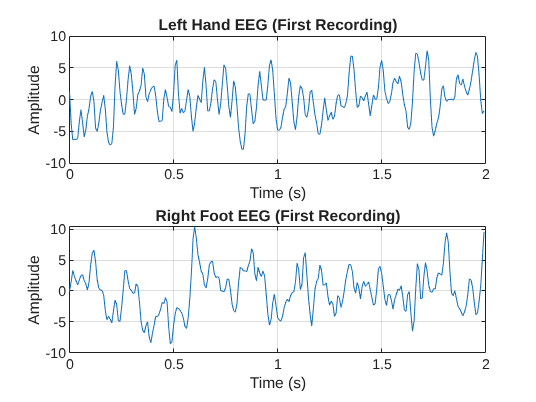

%% Biosignal Processing - Lab 1 Part 2
%% AR-model estimation

clear; close all; clc;

%% Task 3.1 - Load and plot signals
data = load('bci_eeg.mat');

left_hand = data.eeg_left_hand;
right_foot = data.eeg_right_foot;

Fs = 128;
t = (0:size(left_hand,1)-1)/Fs;

figure;

subplot(2,1,1)
plot(t, left_hand(:,1))
xlabel('Time (s)')
ylabel('Amplitude')
title('Left Hand EEG (First Recording)')
grid on

subplot(2,1,2)
plot(t, right_foot(:,1))
xlabel('Time (s)')
ylabel('Amplitude')
title('Right Foot EEG (First Recording)')
grid on

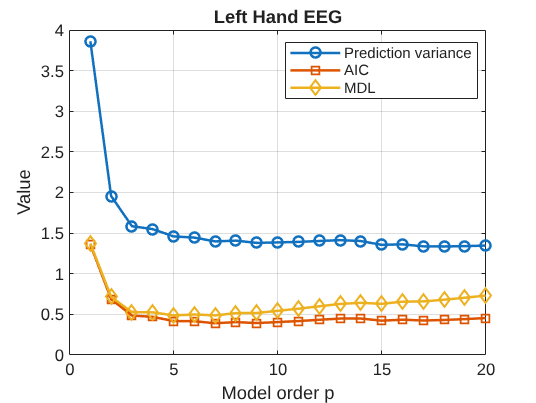

%% Task 3.2 - Left hand

y = left_hand(:,1);

N = length(y);
max_p = 20;

ar_models = cell(max_p,1);

prediction_variance = zeros(max_p,1);
AIC = zeros(max_p,1);
MDL = zeros(max_p,1);

for p = 1:max_p

    ar_models{p} = arx(iddata(y), p);

    prediction_variance(p) = ar_models{p}.NoiseVariance;

    AIC(p) = log(prediction_variance(p)) + (2*p)/N;
    MDL(p) = log(prediction_variance(p)) + (p*log(N))/N;

end

% Plot
figure;
plot(1:max_p, prediction_variance,'o-','LineWidth',1.5)
hold on
plot(1:max_p, AIC,'s-','LineWidth',1.5)
plot(1:max_p, MDL,'d-','LineWidth',1.5)
xlabel('Model order p')
ylabel('Value')
title('Left Hand EEG')
legend('Prediction variance','AIC','MDL','Location','best')
grid on


% Optimal model
p0_left = find(MDL == min(MDL),1);

fprintf('Optimal MDL order (Left Hand) = %d\n', p0_left);

Optimal MDL order (Left Hand) = 5



ar_model_left = arx(iddata(y), p0_left);

present(ar_model_left)


ar_model_left =
Discrete-time AR model: A(z)y(t) = e(t)                                                                                                      
  A(z) = 1 - 1.771 (+/- 0.06164) z^-1 + 1.665 (+/- 0.1232) z^-2 - 1.05 (+/- 0.1478) z^-3 + 0.5546 (+/- 0.123) z^-4 - 0.2311 (+/- 0.0614) z^-5
                                                                                                                                             
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=5
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 64.02% (prediction focus)
FPE: 1.516, MSE: 1.402                           
More information in model's "Report" property.
 


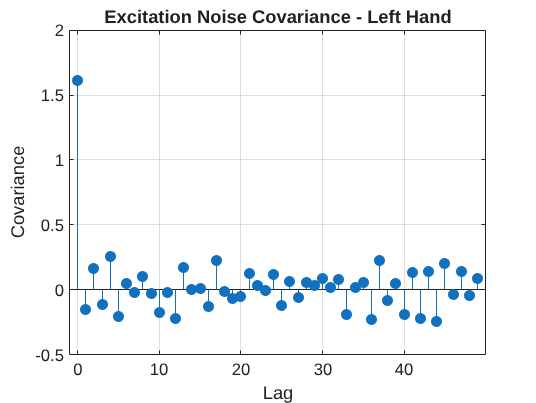


noise_left = filter(ar_model_left.A,1,y);

cov_left = covf(noise_left,50);

figure;
stem(0:49,cov_left,'filled')
xlabel('Lag')
ylabel('Covariance')
title('Excitation Noise Covariance - Left Hand')
grid on

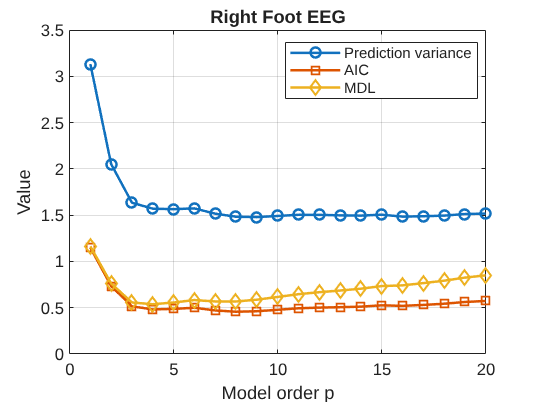

%% Task 3.2 - Right foot

y = right_foot(:,1);

N = length(y);

ar_models = cell(max_p,1);

prediction_variance = zeros(max_p,1);
AIC = zeros(max_p,1);
MDL = zeros(max_p,1);

for p = 1:max_p

    ar_models{p} = arx(iddata(y), p);

    prediction_variance(p) = ar_models{p}.NoiseVariance;

    AIC(p) = log(prediction_variance(p)) + (2*p)/N;
    MDL(p) = log(prediction_variance(p)) + (p*log(N))/N;

end

% Plot
figure;
plot(1:max_p, prediction_variance,'o-','LineWidth',1.5)
hold on
plot(1:max_p, AIC,'s-','LineWidth',1.5)
plot(1:max_p, MDL,'d-','LineWidth',1.5)
xlabel('Model order p')
ylabel('Value')
title('Right Foot EEG')
legend('Prediction variance','AIC','MDL','Location','best')
grid on


% Optimal model
p0_right = find(MDL == min(MDL),1);

fprintf('Optimal MDL order (Right Foot) = %d\n', p0_right);

Optimal MDL order (Right Foot) = 4



ar_model_right = arx(iddata(y), p0_right);

present(ar_model_right)


ar_model_right =
Discrete-time AR model: A(z)y(t) = e(t)                                                                               
  A(z) = 1 - 1.756 (+/- 0.06255) z^-1 + 1.487 (+/- 0.1169) z^-2 - 0.8078 (+/- 0.1174) z^-3 + 0.2115 (+/- 0.06321) z^-4
                                                                                                                      
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data.         
Fit to estimation data: 64.68% (prediction focus)
FPE: 1.619, MSE: 1.521                           
More information in model's "Report" property.
 


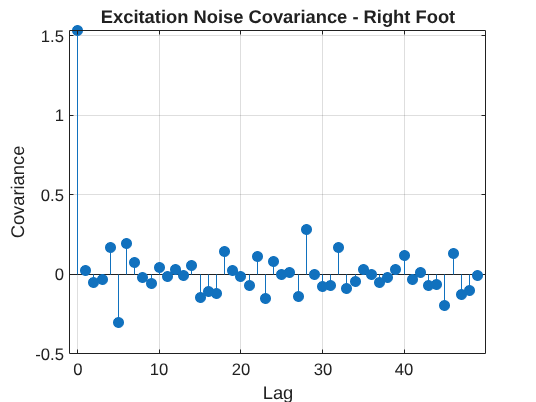


noise_right = filter(ar_model_right.A,1,y);

cov_right = covf(noise_right,50);

figure;
stem(0:49,cov_right,'filled')
xlabel('Lag')
ylabel('Covariance')
title('Excitation Noise Covariance - Right Foot')
grid on

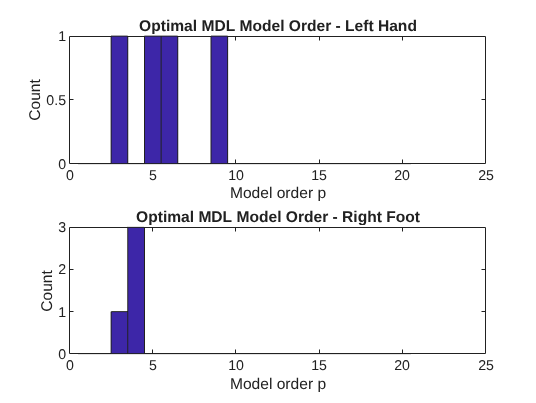

%% Task 3.3 - Optimal MDL for all recordings

num_left = size(left_hand,2);
num_right = size(right_foot,2);

MDL_left = zeros(num_left,1);
MDL_right = zeros(num_right,1);

% Left hand
for i = 1:num_left

    y = left_hand(:,i);
    N = length(y);

    mdl = zeros(max_p,1);

    for p = 1:max_p
        model = arx(iddata(y), p);
        variance = model.NoiseVariance;
        mdl(p) = log(variance) + (p*log(N))/N;
    end

    MDL_left(i) = find(mdl == min(mdl),1);

end

% Right foot
for i = 1:num_right

    y = right_foot(:,i);
    N = length(y);

    mdl = zeros(max_p,1);

    for p = 1:max_p
        model = arx(iddata(y), p);
        variance = model.NoiseVariance;
        mdl(p) = log(variance) + (p*log(N))/N;
    end

    MDL_right(i) = find(mdl == min(mdl),1);

end


%% Histograms

figure;

subplot(2,1,1)
hist(MDL_left, 1:max_p)
xlabel('Model order p')
ylabel('Count')
title('Optimal MDL Model Order - Left Hand')

subplot(2,1,2)
hist(MDL_right, 1:max_p)
xlabel('Model order p')
ylabel('Count')
title('Optimal MDL Model Order - Right Foot')

%% Task 3.4 - Selection

all_orders = [MDL_left; MDL_right];

p0 = mode(all_orders);

fprintf('Selected common model order p0 = %d\n', p0);

Selected common model order p0 = 4


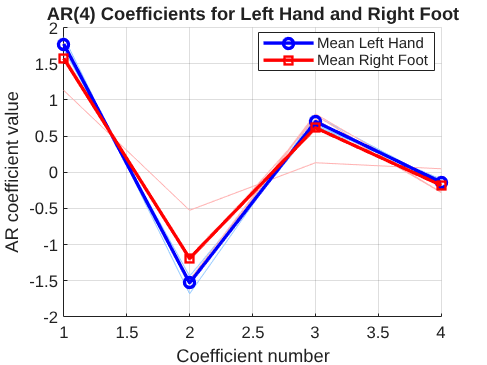

%% Task 3.5 - AR coefficients 

left_coefficients = zeros(num_left,p0);
right_coefficients = zeros(num_right,p0);

% Left hand
for i = 1:num_left

    model = arx(iddata(left_hand(:,i)), p0);

    % Remove leading 1
    left_coefficients(i,:) = -model.A(2:end);

end

% Right foot
for i = 1:num_right

    model = arx(iddata(right_foot(:,i)), p0);

    right_coefficients(i,:) = -model.A(2:end);

end

%% Plot AR coefficients

figure;
hold on;

% Individual recordings 
plot(left_coefficients', 'Color', [0.6 0.8 1], 'HandleVisibility', 'off');
plot(right_coefficients', 'Color', [1 0.7 0.7], 'HandleVisibility', 'off');

% Mean coefficients
plot(mean(left_coefficients), 'bo-', 'LineWidth', 2, 'MarkerSize', 6);
plot(mean(right_coefficients), 'rs-', 'LineWidth', 2, 'MarkerSize', 6);

xlabel('Coefficient number');
ylabel('AR coefficient value');
title(sprintf('AR(%d) Coefficients for Left Hand and Right Foot', p0));

legend('Mean Left Hand', 'Mean Right Foot', 'Location', 'best');

grid on;